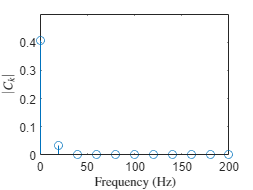

clf;
clear;
%% Problem 1-1c
f = 0:20:200; % Natural frequency is 20, so frequency spectrum should be divided into intervals of 20
k = 0:1:(200/20); % Want 11 points from 0 to 200
C_k = ((-1).^(-k) + (-1).^k)./(pi*(1+4*k.^2)); % e^-j*pi*k replaced with (-1)^(-k), e^j*pi*k replaced with (-1)^k
P = [C_k(1)^2 2*C_k(2:end).^2]; % One-sided power spectrum, C_0 not included in the *2 operation

Figure1 = figure(1);
set(Figure1, 'defaulttextinterpreter', 'latex')
stem(f,P) % Plotting the one-sided power spectrum using formula 2*C_k^2
xlim([f(1), f(end)])
xlabel('Frequency (Hz)')
ylabel('$|C_k|$')

## Problem 1-3b

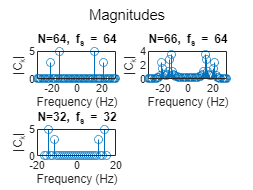


clear
t_start = 0;

% Part (i)
N_1 = 64;
f_s1 = 64;
[C_k1, f_k1] = problem_3_program(t_start,f_s1,N_1); 

% Part (ii)
N_2 = 66;
f_s2 = 64;
[C_k2, f_k2] = problem_3_program(t_start,f_s2,N_2); 

% Part (iii)
N_3 = 32;
f_s3 = 32;
[C_k3, f_k3] = problem_3_program(t_start, f_s3, N_3);


% Plotting magnitudes
figure(2);
sgtitle('Magnitudes')
subplot(2,2,1)
stem(f_k1, abs(C_k1))
title('N=64, f_s = 64')
xlabel('Frequency (Hz)')
ylabel('|C_k|')
subplot(2,2,2)
stem(f_k2, abs(C_k2))
title('N=66, f_s = 64')
xlabel('Frequency (Hz)')
ylabel('|C_k|')
subplot(2,2,3)
stem(f_k3,abs(C_k3))
title('N=32, f_s = 32')
xlabel('Frequency (Hz)')
ylabel('|C_k|')

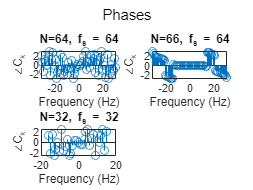

orient TALL

% Plotting Phases
figure(3);
sgtitle('Phases')
subplot(2,2,1)
stem(f_k1, angle(C_k1))
title('N=64, f_s = 64')
xlabel('Frequency (Hz)')
ylabel('\angle{C_k}')
subplot(2,2,2)
stem(f_k2, angle(C_k2))
title('N=66, f_s = 64')
xlabel('Frequency (Hz)')
ylabel('\angle{C_k}')
subplot(2,2,3)
stem(f_k3,angle(C_k3))
title('N=32, f_s = 32')
xlabel('Frequency (Hz)')
ylabel('\angle{C_k}')


orient TALL


## Problem 1-3c

The fundamental frequency of the continuous signal is 7 Hz and the period is  0.1429 second.

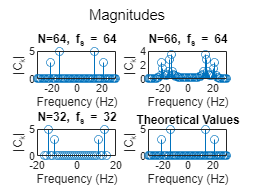

C_k = zeros(1,length(f_k1));
C_k(f_k1==-21) = 3; C_k(f_k1==21) = 3;
C_k(f_k1==-14) = -5j; C_k(f_k1==14) = -5j;
figure(2);
subplot(2,2,4)
stem(f_k1, abs(C_k))
title('Theoretical Values')
xlabel('Frequency (Hz)')
ylabel('|C_k|')
sgtitle('Magnitudes')

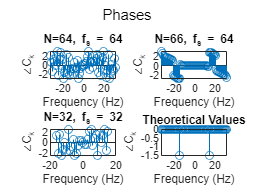


figure(3);
subplot(2,2,4)
stem(f_k1, angle(C_k))
title('Theoretical Values')
xlabel('Frequency (Hz)')
ylabel('\angle{C_k}')
sgtitle('Phases')

## Problem 1-4

% Part d
clear;
f_k = [0 100 200 300 400 500];
C_k = [-2 0 sqrt(2)-1j*sqrt(2) -5 0 7j];
f_1 = 100;
num_periods = 5;
t0 = -1;
[t,x] = problem_4c_program(f_k, C_k, t0, f_1, num_periods);
figure;
plot(t,x)

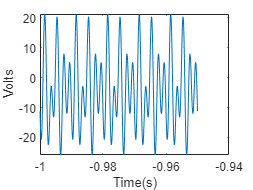

xlabel('Time(s)')
ylabel('Volts')


% Part e
figure;
k1 = 0:3;
k2 = 0:30;
k3 = 0:90;

f_k1 = 20*k1;
f_k2 = 20*k2; 
f_k3 = 20*k3;

C_k1 = [exp(-1j*pi.*k1) + exp(1j*pi.*k1)]./(pi*(1+4.*k1.^2));
C_k2 = [exp(-1j*pi.*k2) + exp(1j*pi.*k2)]./(pi*(1+4.*k2.^2));
C_k3 = [exp(-1j*pi.*k3) + exp(1j*pi.*k3)]./(pi*(1+4.*k3.^2));

[t1,x1] = problem_4c_program(f_k1, C_k1, 0, 20, 4);
[t2,x2] = problem_4c_program(f_k2, C_k2, 0, 20, 4);
[t3,x3] = problem_4c_program(f_k3, C_k3, 0, 20, 4);

figure;
plot(t1,abs(x1), t2,abs(x2), t3,x3)

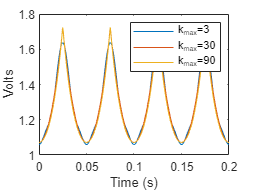

legend('k_{max}=3', 'k_{max}=30', 'k_{max}=90')
xlabel('Time (s)')
ylabel('Volts')

The 3 results are similar to each other. However, the results with a higher maximum value of k is less smooth and has greater resolution. These are not close to the true signal at all, likely due incorrect Fourier Series coefficients produced in Problem 1.

function [t,x] = problem_4c_program(f_k, C_k, t0, f_1, num_periods)
T_p = 1/f_1;
k = 0:length(f_k)-1;
f_s = 20*max(f_k);
t = t0:1/f_s:t0+num_periods*T_p;
for i = 1:length(t)
    x(i) = sum(2*C_k.*exp(1j*2*pi*k.*t(i)/T_p)); % k indexing starts from 0 in my equation, so need to multiply by 2 to capture negative k values
end
end

function [c_k, f_k] = problem_3_program(t_start, f_s, N)
t_end = t_start+N*1/f_s;
t = t_start:1/f_s:t_end-1/f_s;
n = 0:N-1;
x_n = 10*sin(2*pi*14*t)+ 6*cos(2*pi*21*t);
[x_k, f_k] = mydft(x_n, n, N, f_s);
c_k = x_k/N;
end
